## ECE572 - HW2

### Reza Jahani - Rjahani@ncsu.edu

% Problem 1
% a
Q = [2 1;1 2];


grad_func = @(x) Q*x;
x0 = [0.8;-0.25];

epsilon = 0.075;

grad_f = grad_func(x0);
x1 = x0 - epsilon*(grad_f/norm(grad_f));
grad_f = grad_func(x1);
x2 = x1 - 2*epsilon*(grad_f/norm(grad_f));
grad_f = grad_func(x2);
x3 = x2 - 4*epsilon*(grad_f/norm(grad_f));

% b
rho = 1 - 0.618;
a = x0;
b = x3;
s = a + rho*(b-a);
t = a + (1-rho)*(b-a);
f1 = func1(s);
f2 = func1(t);

a_val = {a};
b_val = {b};
f_a = [func1(a)];
f_b = [func1(b)];

N = 1000;
for n=1:N
    if f1 < f2
        b = t;
        t = s;
        s = a +rho(b-a);
        f1 = func1(s);
        f2 = f1;
    else
        a = s;
        s = t;
        t = a + (1-rho)*(b-a);
        f1 = f2;
        f2 = func1(t);
    end
    a_val{end+1} = a;
    b_val{end+1} = b;
    f_a(end+1) = func1(a);
    f_b(end+1) = func1(b);

    disp("a_k - b_k");
    disp([a, b]);
    disp("f(a) - f(b)")
    disp([func1(a), func1(b)])
    disp("--------------------------")

    if norm(b-a)<=0.01
        break;
    end
end

a_k - b_k


    0.6009    0.2788
   -0.2652   -0.2897



f(a) - f(b)


    0.2720    0.0809



--------------------------


a_k - b_k


    0.4779    0.2788
   -0.2745   -0.2897



f(a) - f(b)


    0.1725    0.0809



--------------------------


a_k - b_k


    0.4018    0.2788
   -0.2803   -0.2897



f(a) - f(b)


    0.1274    0.0809



--------------------------


a_k - b_k


    0.3548    0.2788
   -0.2839   -0.2897



f(a) - f(b)


    0.1058    0.0809



--------------------------


a_k - b_k


    0.3258    0.2788
   -0.2861   -0.2897



f(a) - f(b)


    0.0948    0.0809



--------------------------


a_k - b_k


    0.3078    0.2788
   -0.2875   -0.2897



f(a) - f(b)


    0.0889    0.0809



--------------------------


a_k - b_k


    0.2967    0.2788
   -0.2884   -0.2897



f(a) - f(b)


    0.0856    0.0809



--------------------------


a_k - b_k


    0.2899    0.2788
   -0.2889   -0.2897



f(a) - f(b)


    0.0837    0.0809



--------------------------


a_k - b_k


    0.2856    0.2788
   -0.2892   -0.2897



f(a) - f(b)


    0.0826    0.0809



--------------------------


% c 
%%%%%%%%%%%%%% Fibonacci Method

seq = [2 3 5 8 13 21 34 55 89];

rho = 1 - seq(end-1)/seq(end);

a = x0;
b = x3;
s = a + rho*(b-a);
t = a + (1-rho)*(b-a);
f1 = func1(s);
f2 = func1(t);

a_val = {a};
b_val = {b};
f_a = [func1(a)];
f_b = [func1(b)];
rho_k = [rho];

N = length(seq);
for n=N:-1:2
    rho = 1 - seq(n-1)/seq(n);
    if f1 < f2
        b = t;
        t = s;
        s = a +rho(b-a);
        f1 = func1(s);
        f2 = f1;
    else
        a = s;
        s = t;
        t = a + (1-rho)*(b-a);
        f1 = f2;
        f2 = func1(t);
    end
    a_val{end+1} = a;
    b_val{end+1} = b;
    f_a(end+1) = func1(a);
    f_b(end+1) = func1(b);
    rho_k(end+1) = rho;

    % disp("a_k - b_k");
    % disp([a, b]);
    % disp("f(a) - f(b)")
    % disp([func1(a), func1(b)])
    % disp("--------------------------")

    if norm(b-a)<=0.01
        break;
    end
end

    fprintf("k  |   rho_k  |   ak                   |      bk               |     f(ak)    |       f(bk)");

k  |   rho_k  |   ak                   |      bk               |     f(ak)    |       f(bk)

for k=1:length(rho_k)
    fprintf("-------------------------------");
    fprintf('%-3d | %-8.6f | [%.6f, %.6f] | [%.6f, %.6f] | %-12.6f | %-12.6f ', ...
        k-1, rho_k(k), a_val{k}, b_val{k}, f_a(k), f_b(k))
end

-------------------------------

0   | 0.382022 | [0.800000, -0.250000] | [0.278755, -0.289719] | 0.502500     | 0.080881     

-------------------------------

1   | 0.382022 | [0.600873, -0.265174] | [0.278755, -0.289719] | 0.272029     | 0.080881     

-------------------------------

2   | 0.381818 | [0.477882, -0.274546] | [0.278755, -0.289719] | 0.172546     | 0.080881     

-------------------------------

3   | 0.382353 | [0.401811, -0.280342] | [0.278755, -0.289719] | 0.127399     | 0.080881     

-------------------------------

4   | 0.380952 | [0.354785, -0.283926] | [0.278755, -0.289719] | 0.105754     | 0.080881     

-------------------------------

5   | 0.384615 | [0.325806, -0.286134] | [0.278755, -0.289719] | 0.094798     | 0.080881     

-------------------------------

6   | 0.375000 | [0.307719, -0.287512] | [0.278755, -0.289719] | 0.088881     | 0.080881     

-------------------------------

7   | 0.400000 | [0.296851, -0.288340] | [0.278755, -0.289719] | 0.085667     | 0.080881     

-------------------------------

8   | 0.333333 | [0.289616, -0.288892] | [0.278755, -0.289719] | 0.083668     | 0.080881     

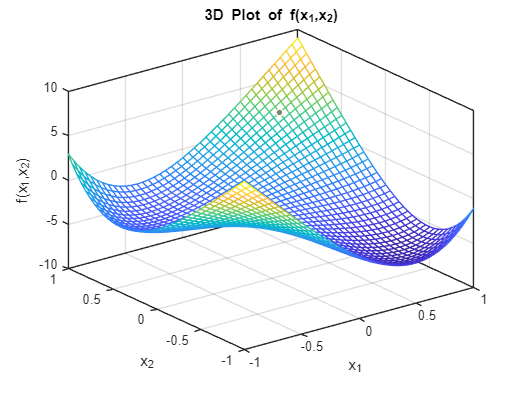

% Problem 2
x1 = -1:0.05:1;
x2 = -1:0.05:1;

[X1,X2] = meshgrid(x1,x2);

f = (X1-X2).^4 + 12*X1.*X2 - X1 + X2 -3;

mesh(X1,X2,f);
xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1,x_2)');
title('3D Plot of f(x_1,x_2)');
box on;

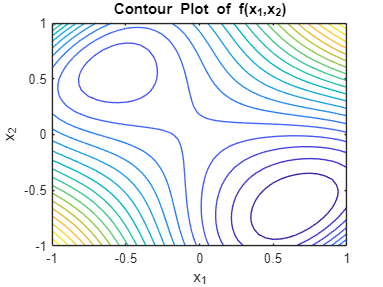

contour(X1,X2,f,20);
xlabel('x_1');
ylabel('x_2');
title('Contour Plot of f(x_1,x_2)');
box on;

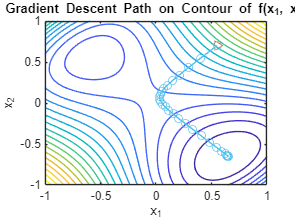

% Problem 3

f = @(x1,x2) (x1 - x2).^4 + 12*x1.*x2 - x1 + x2 - 3;
grad_f = @(x) [4*(x(1)-x(2))^3 + 12*x(2) - 1;
   -4*(x(1)-x(2))^3 + 12*x(1) + 1];

alpha = 0.02;
N = 100;
err = 1e-5;

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 20); hold on;
xlabel('x_1'); ylabel('x_2');
title('Gradient Descent Path on Contour of f(x_1, x_2)');

x0 = [0.55;0.7];

path = x0;
x = x0;

for n=1:N
   g = grad_f(x);
   x_new = x - alpha*g;

   if norm(x-x_new) <= err
        break;
   end

   x = x_new;
   path = [path, x];

   plot(path(1,:), path(2,:), '-o')

end

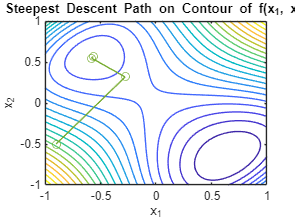

% Steepest Descent

f = @(x1,x2) (x1 - x2).^4 + 12*x1.*x2 - x1 + x2 - 3;
f_val = @(x) f(x(1),x(2));
grad_f = @(x) [4*(x(1)-x(2))^3 + 12*x(2) - 1;
   -4*(x(1)-x(2))^3 + 12*x(1) + 1];

alpha = 0.02;
N = 100;
err = 1e-5;

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 20); hold on;
xlabel('x_1'); ylabel('x_2');
title('Steepest Descent Path on Contour of f(x_1, x_2)');

x0 = [-0.9;-0.5];

path = x0;
x = x0;

for n=1:N
   g = grad_f(x);
   d = -g;
   phi = @(alph) f_val(x + alph*d);
   alpha = fminbnd(phi, 0, 1);

   x_new = x - alpha*g;

   if norm(x-x_new) <= err
        break;
   end

   x = x_new;
   path = [path, x];

   plot(path(1,:), path(2,:), '-o')

end

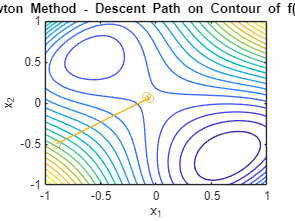

% Problem 4
f = @(x1,x2) (x1 - x2).^4 + 12*x1.*x2 - x1 + x2 - 3;
grad_f = @(x) [4*(x(1)-x(2))^3 + 12*x(2) - 1;
   -4*(x(1)-x(2))^3 + 12*x(1) + 1];
H_f = @(x) [12*(x(1)-x(2))^2 -12*(x(1)-x(2))^2+12;
            -12*(x(1)-x(2))^2+12 12*(x(1)-x(2))^2];


N = 100;
err = 1e-5;

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 20); hold on;
xlabel('x_1'); ylabel('x_2');
title('Newton Method - Descent Path on Contour of f(x_1, x_2)');

x0 = [-0.9;-0.5];

path = x0;
x = x0;

for n=1:N
   g = grad_f(x);
   H = H_f(x);
   x_new = x - inv(H)*g;

   if norm(x-x_new) <= err
        break;
   end

   x = x_new;
   path = [path, x];

   plot(path(1,:), path(2,:), '-o')

end

%%% Functions

function y = func1(x)
    Q = [2 1;1 2];
    y = 1/2 * transpose(x) * Q * x;
end